# Pb6

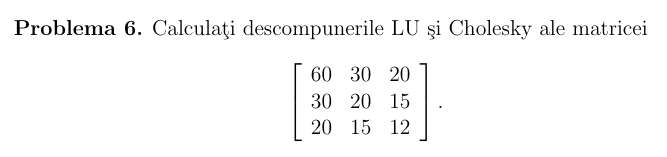

## Descompunerea LU

LU e fara pivotare comparativ cu LUP

function [L, U] = lu_fara_pivotare(A)
% INPUT:
%   A - matricea coeficientilor (n x n), presupusa nesingulara
%
% OUTPUT:
%   L - matrice triunghiulara inferiora cu 1 pe diagonala
%   U - matrice triunghiulara superiora
%
% Metoda: Descompunere LU fara pivotare
% A = L * U

    n = size(A, 1);     % dimensiunea matricei
    L = eye(n);         % initializare L cu identitate
    U = A;              % initial, U este A

    for k = 1:n-1
        for i = k+1:n
            if U(k, k) == 0
                error('Pivot nul pe pozitia (%d,%d). Algoritmul necesita pivotare.', k, k);
            end

            % Calculam factorul de eliminare
            L(i, k) = U(i, k) / U(k, k);

            % Actualizam linia i din U
            U(i, :) = U(i, :) - L(i, k) * U(k, :);
        end
    end
end


A = [60 30 20;
     30 20 15;
     20 15 12];

% Verificam daca putem aplica Cholesky
is_sym = issymmetric(A);
is_pos_def = all(eig(A) > 0);

fprintf("Este simetrica?         %d\n", is_sym);

Este simetrica?         1


fprintf("Este pozitiv definita?  %d\n\n", is_pos_def);

Este pozitiv definita?  1




% Apel LU
[L, U] = lu_fara_pivotare(A);
fprintf("Descompunere LU:\n");

Descompunere LU:


disp("L = "); disp(vpa(L, 12));

L = 


$$\left(\begin{array}{ccc} 1.0 & 0 & 0\\ 0.5 & 1.0 & 0\\ 0.333333333333 & 1.0 & 1.0 \end{array}\right)$$

disp("U = "); disp(vpa(U, 12));

U = 


$$\left(\begin{array}{ccc} 60.0 & 30.0 & 20.0\\ 0 & 5.0 & 5.0\\ 0 & 0 & 0.333333333333 \end{array}\right)$$

disp("Verificare L*U = A:"); disp(vpa(L*U, 12));

Verificare L*U = A:


$$\left(\begin{array}{ccc} 60.0 & 30.0 & 20.0\\ 30.0 & 20.0 & 15.0\\ 20.0 & 15.0 & 12.0 \end{array}\right)$$


% Apel Cholesky, daca este cazul
if is_sym && is_pos_def
    R = chol(A);  % forma superioara
    fprintf("\nDescompunere Cholesky (A = R'' * R):\n");
    disp("R = "); disp(vpa(R, 9));
    disp("Verificare R' * R = A:"); disp(vpa(R' * R, 12));
end


Descompunere Cholesky (A = R'' * R):


R = 


$$\left(\begin{array}{ccc} 7.74596669 & 3.87298335 & 2.5819889\\ 0 & 2.23606798 & 2.23606798\\ 0 & 0 & 0.577350269 \end{array}\right)$$

Verificare R' * R = A:


$$\left(\begin{array}{ccc} 60.0 & 30.0 & 20.0\\ 30.0 & 20.0 & 15.0\\ 20.0 & 15.0 & 12.0 \end{array}\right)$$